%fitting data to a theoretical RET (resonance energy transfer) model

%distance values (Å) – from experiment
r = [10, 15, 20, 25, 30, 35, 40, 45, 50];

%RET efficiencies (0 to 1) – from experiment
E_T = [0.96, 0.91, 0.85, 0.66, 0.48, 0.32, 0.20, 0.12, 0.05];

%model: RET efficiency as a function of R₀ and distance
model = @(R_0, r) 1./(1+(r./R_0).^6);

%initial guess for R₀
R_0_init = 1;

%fit R₀ to minimize squared error between model and data
R_0 = lsqcurvefit(model, R_0_init, r, E_T);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


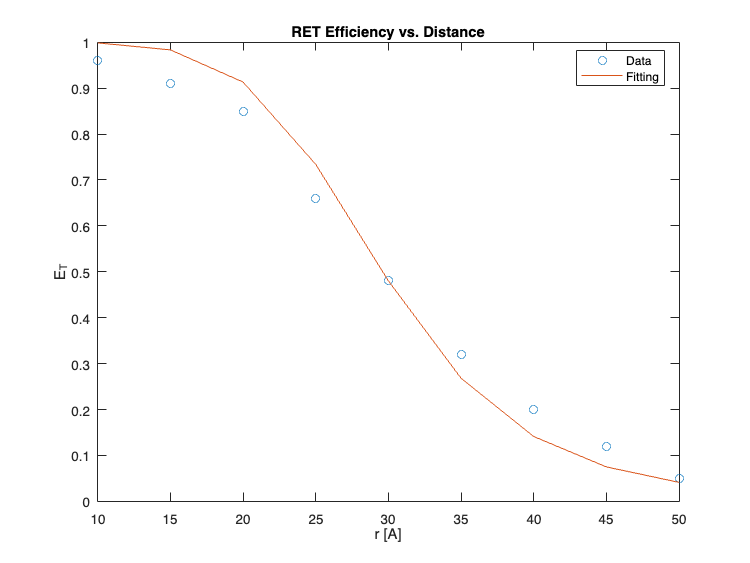


%plotting
figure;
plot(r, E_T, 'o', 'DisplayName', 'Data'); %data points
hold on; %keep figure open
plot(r, model(R_0, r), 'DisplayName', 'Fitting'); %fitted curve
xlabel('r [A]');
ylabel('E_T');
title('RET Efficiency vs. Distance');
legend('Location', 'best');


%print fitted R₀
fprintf('Fitting parameter R_0: %.2f A\n', R_0);

Fitting parameter R_0: 29.61 A
